        1965

   423

   113

    23

     5



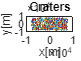


% PLOT CENTERS OF CRATERS
%figure(9)
% Definition of the maximum age to be considered for plotting
Headers = {'PosX', 'PosY', 'Radius'};
rowCounter = 1;
t = table('Size', [0, length(Headers)], 'VariableTypes', {'double', 'double', 'double'}, 'VariableNames', Headers);
for index=6:10
    craterList = readtable("CraterList_txt_layer_" + index + ".csv");
    CraterListtxtlayer_AgeLim_Max = 90;
    CraterListtxtlayer_AgeLim_Min = 50;
    CraterCounter=0;
    % for i=1:length(craterList.PosX)
    %        xc(i) = craterList.PosX(i);
    %        yc(i) = craterList.PosY(i);
    %        if craterList.Age(i) < CraterListtxtlayer_AgeLim
    %            CraterCounter=CraterCounter+1;    
    %             plot(xc(i),yc(i),'.')
    %             hold on;
    %        end
    % end
    % title('Craters Centers')
    % xlabel('x[m]');
    % ylabel('y[m]');
    
    % PLOT CRATERS
    figure(1)
    for i=1:length(craterList.PosX)
           xc(i) = craterList.PosX(i);
           yc(i) = craterList.PosY(i);
           r(i) = craterList.Diameter(i)/2;
           theta = linspace(0,2*pi);
           if craterList.Age(i) <= CraterListtxtlayer_AgeLim_Max && craterList.Age(i) >= CraterListtxtlayer_AgeLim_Min && craterList.Diameter(i) < 300
               CraterCounter=CraterCounter+1;
               newRow = table(xc(i), yc(i), r(i), 'VariableNames', Headers);
               t = [t; newRow];
               t.PosX(rowCounter) = craterList.PosX(i);
               t.PosY(rowCounter) = craterList.PosY(i);
               t.Radius(rowCounter) = craterList.Diameter(i)/2;
               %t.Age(rowCounter) = craterList.Age(i);
               x = r(i)*cos(theta) + xc(i);
               y = r(i)*sin(theta) + yc(i);
               plot(x,y);
               hold on;  
               rowCounter = rowCounter + 1;
           end
    end
    disp(CraterCounter);
    title('Craters');
    xlabel('x[m]');
    ylabel('y[m]');
end

writetable(t, 'CraterMapRadius.csv');
